  %Load the Library with all functions
addpath('../Library')
%Define the physical constant
mli=9.988346*10^-27;  %kg
hbar=1.0545718*10^(-34); %SI
hh=2*pi*hbar;%SI Planck constant
omega=23.9*2*pi; %in rad/s
pixellength=1.44*10^-6; %in m
sigma0=0.215*10^-12/2; %in m^2
warning('off','all');

Using the result from 30 points polynomial fitting to get the T/T_F

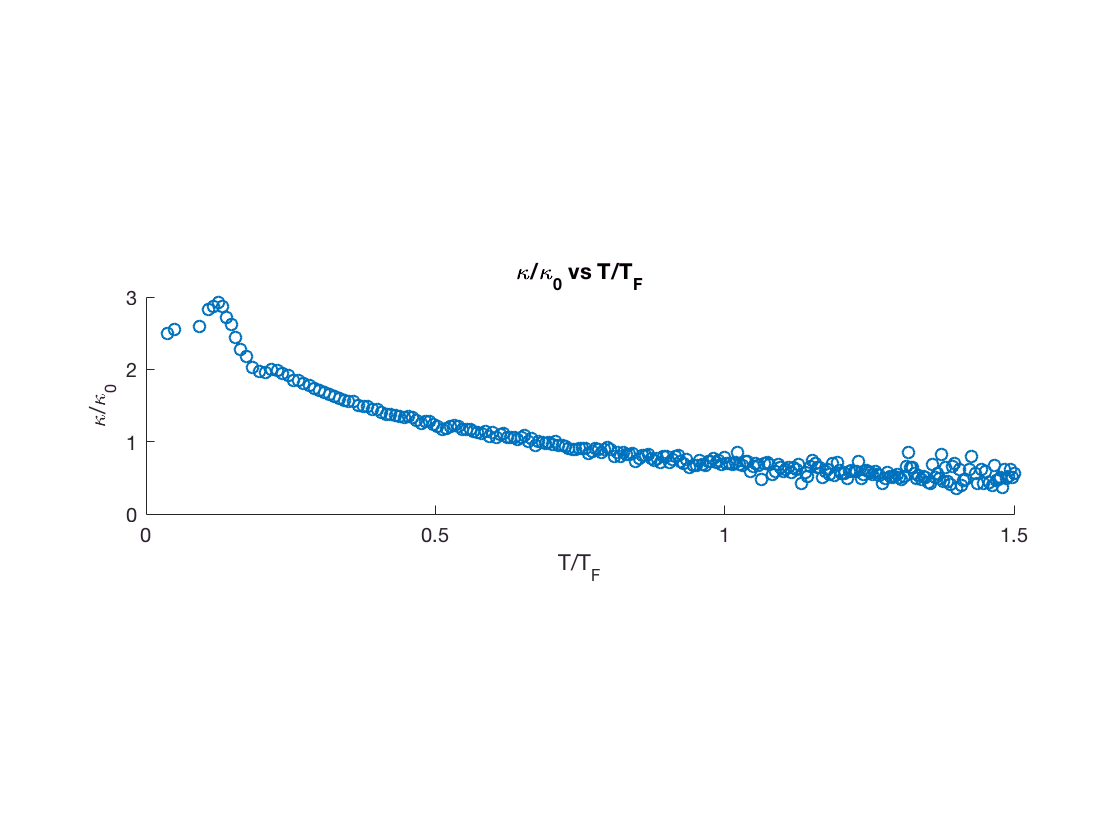

load('30PointsPoly');

Pt=Ptbin30;
Kt=KtMean30;
% the cutoff value for the pressure.
Ptcutoff=5.58;
Ttcutoff=1.5;

Kt(Pt>Ptcutoff)=[];
Pt(Pt>Ptcutoff)=[];
Pt(isnan(Kt))=[];
Kt(isnan(Kt))=[];

Tt=GetTTilde(Pt,Kt,Ttcutoff);
scatter(Tt,Kt)
pbaspect([1 0.25 1])
xlabel('T/T_F');
ylabel('\kappa/\kappa_0')
title('\kappa/\kappa_0 vs T/T_F');

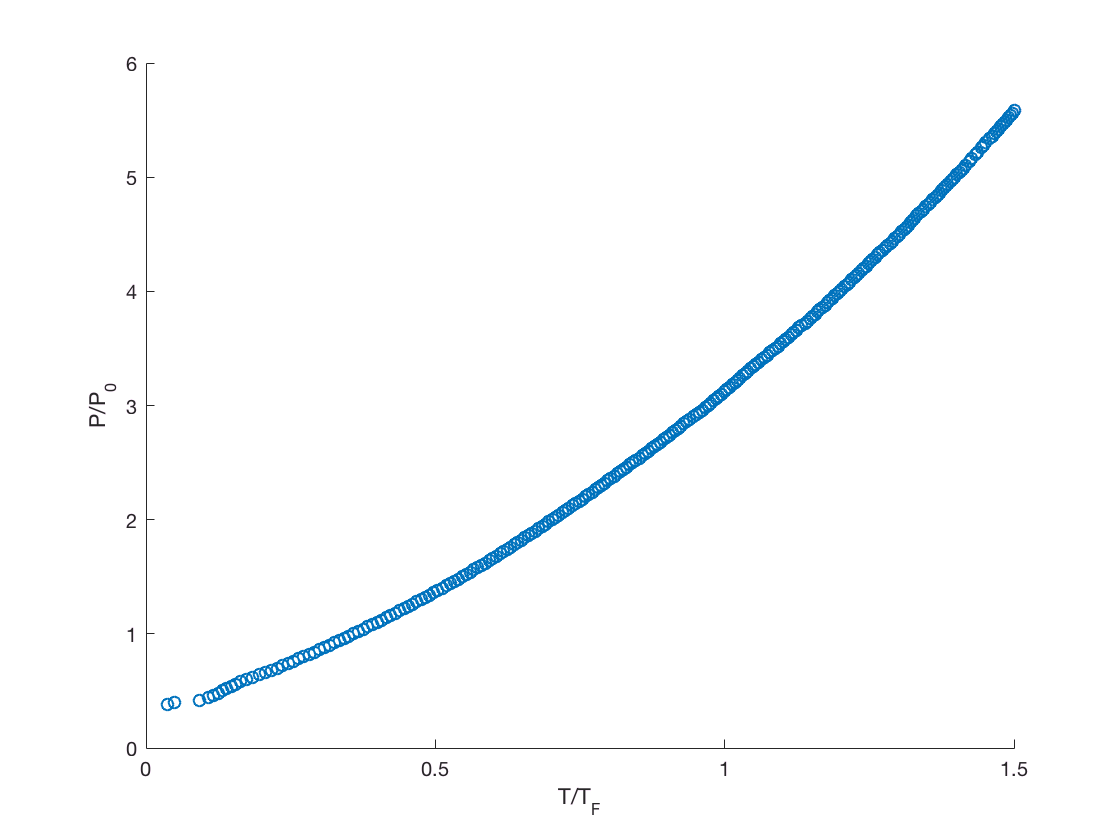

scatter(Tt,Pt)
xlabel('T/T_F');ylabel('P/P_0');

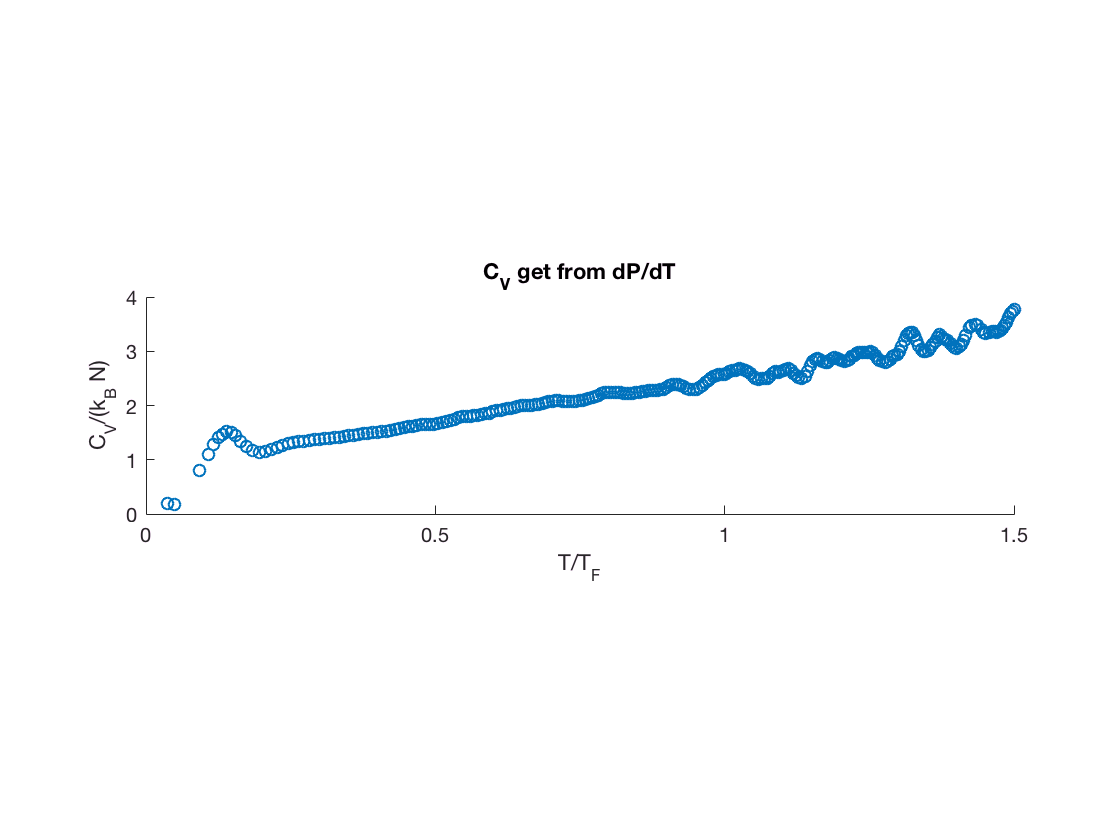

%% try to get C_V with dP/dT
Cvt = GetCvTildeDerivitive( Pt,Tt,4,2 );
scatter(Tt,Cvt)
pbaspect([1 0.25 1])
ylim([0,4]);
xlabel('T/T_F');
ylabel('C_V/(k_B N)')
title('C_V get from dP/dT');

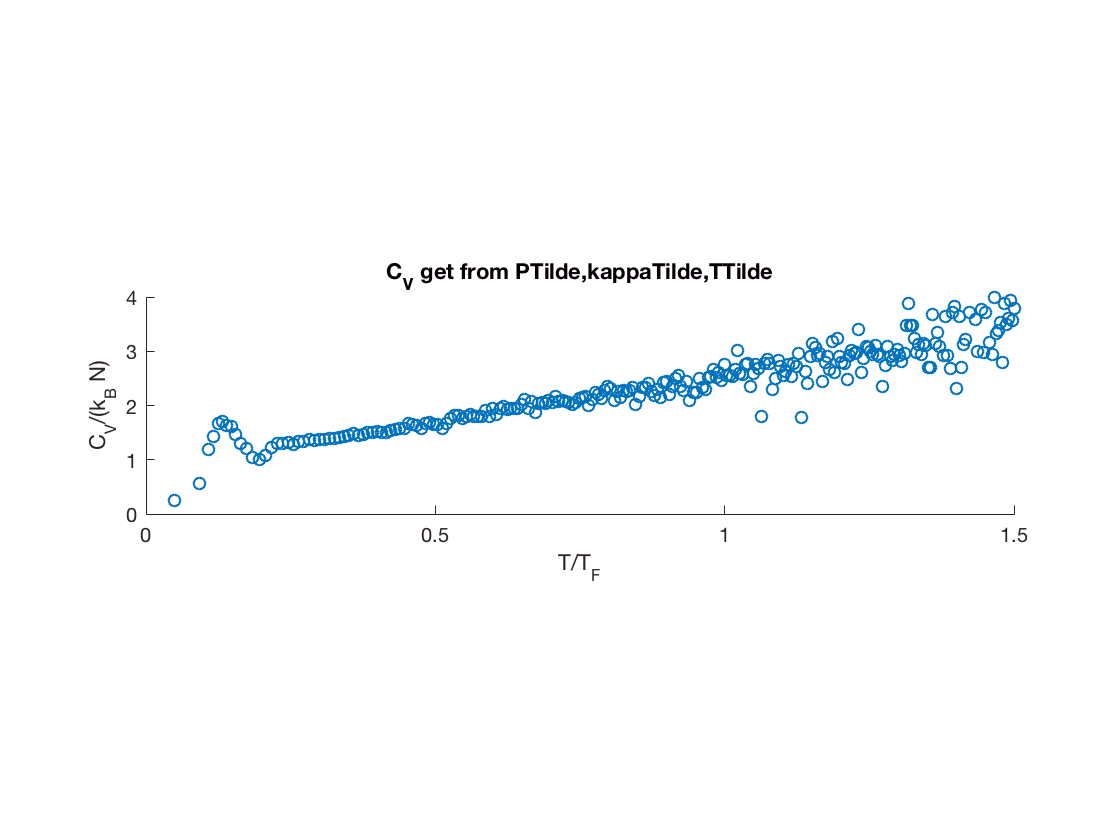

%%Try to get C_V with P,Kappa and T
Cvt_PKT = GetCvTilde( Pt,Kt,Tt );
scatter(Tt,Cvt_PKT)
pbaspect([1 0.25 1])
ylim([0,4]);
xlabel('T/T_F');
ylabel('C_V/(k_B N)')
title('C_V get from PTilde,kappaTilde,TTilde');

% [ KappaTilde, PTilde, TTilde, Z_vec ] =  VirialUnitarity(  5, 80, 30000 , 3 );
% CvTilde =  GetCvTilde( PTilde,KappaTilde,TTilde);
% scatter(TTilde,CvTilde)
% pbaspect([1 0.25 1]);
% ylim([0,5]);
% xlabel('T/T_F');
% ylabel('C_V/(k_B N)')
% title('\C_V get from P,\kappa, and T');

% [ KappaTildeP, PTildeP, TTildeP, Z_vec ]=IdealFermiEOS( 5, 20,4000 )
% [ KappaTildeV, PTildeV,TTildeV, ~] = VirialUnitarity( 5,20, 4000, 3 );
% % plot(PTildeV,KappaTildeV);
% % hold on
% % scatter(PTildeP,KappaTildeP);
% % hold off
% 
% [TTildeP,B]=sort(TTildeP);
% KappaTildeP=KappaTildeP(B);
% PTildeP=PTildeP(B);
% 
% [TTildeV,B]=sort(TTildeV);
% KappaTildeV=KappaTildeV(B);
% PTildeV=PTildeV(B);
% 
% CvTildeP =  GetCvTilde( PTildeP,KappaTildeP,TTildeP);
% CvTildeV =  GetCvTilde( PTildeV,KappaTildeV,TTildeV);
% CvTildeV2= GetCvTildeDerivitive( PTildeV,TTildeV ,4,1);
% 
% plot(TTildeV,CvTildeV2)
% % TTildeP=GetTTilde(PTildeP,KappaTildeP,7.5);
% % plot(TTildeP,PTildeP);